# Similarity Transformations

## System- Quarter Car Suspension System

%-- Refer doc for details on model

## STEP 1- A- A State Space Model Development -SISO Model - Continious Time Domain

%-- Define parameters
mb = 300;    % kg
mw = 60;     % kg
bs = 1000;   % N/m/s
ks = 16000 ; % N/m
kt = 190000; % N/m
%---- Define State Space Represenation
A = [ 0 1 0 0; [-ks -bs ks bs]/mb ; ...
      0 0 0 1; [ks bs -ks-kt -bs]/mw];
B = [0;
    1/mb ; 
     0; 
    -1/mw];
C = [1 0 0 0; 
    1 0 -1 0;
    A(2,:)];
D = [0;0;B(1,:)];
%--- Develop State Space Model
states = {'chassis position xb (m)';'chassis velocity  (m/s)';...
                  'wheel position xw (m)';'wheel velocity (m/s)'};
inputs = {'fs'};
outputs = {'Chassis Position','Suspension Deflection','Chassis Acceleration'};
qcar_CT = ss(A,B,C,D,'statename',states,'inputname',inputs,'outputname',outputs);
%------------------

## Reduced order suspension model

%Let us consider the states as
% x1 = xb-xw, x2 = xb'-xw', u = fs, u2 = -kt(xw-r) = ft 
% % Now if we model the state space dyanamics, we get 
% m = (1/mb) + (1/mw); 
% A = [0 1; -m*ks -m*bs]; 
% B = [0,0;m,1/mw]; 
% % Consider the ouputs as x1, chassis accleration 
% C = [1 0; -ks/mb -bs/mb]; 
% D = [0 , 0;1/mb, 0]; 
% %--- Develop State Space Model 
% states = {'Suspension Deflection (m)';'Suspension Deflection velocity (m/s)';}; 
% inputs = {'fs' ;'ft'}; 
% outputs = {'Suspension Deflection','Chassis Acceleration'}; 
% qcar_CTn = ss(A,B,C,D,'statename',states,'inputname',inputs,'outputname',outputs); 
% %------------------ % Getting the Transfer Function Model 
% [NUM1,DEN1] = ss2tf(qcar_CTn.a,qcar_CTn.b,qcar_CTn.c,qcar_CTn.d,1);
% % TF respect to input 1 i.e. fs 
% [NUM2,DEN2] = ss2tf(qcar_CTn.a,qcar_CTn.b,qcar_CTn.c,qcar_CTn.d,2); 
% % TF respect to input 2 i.e. ft
%H1_11 = tf(NUM1(1,:),DEN1); 
% % TF of output 1 and input 1 
% H1_12 = tf(NUM1(2,:),DEN1); 
% % TF of output 2 and input 1 
% H1_21 = tf(NUM1(1,:),DEN2); 
% % TF of output 1 and input 2 
% H1_22 = tf(NUM1(2,:),DEN2); 
% % TF of output 2 and input 2

## Convert to Diagnoal canonical form

%--- Based on theoritical technique--- Lec 5
[Eig_vec,Eig_val] = eig(qcar_CT.A);
T_DCF = Eig_vec;
A_DCF = inv(T_DCF)*qcar_CT.A*T_DCF;
B_DCF = inv(T_DCF)*qcar_CT.B;
C_DCF = qcar_CT.C*T_DCF;
D_DCF = qcar_CT.D;
Pol_DCF = eig(A_DCF);

## Response Check using DCF

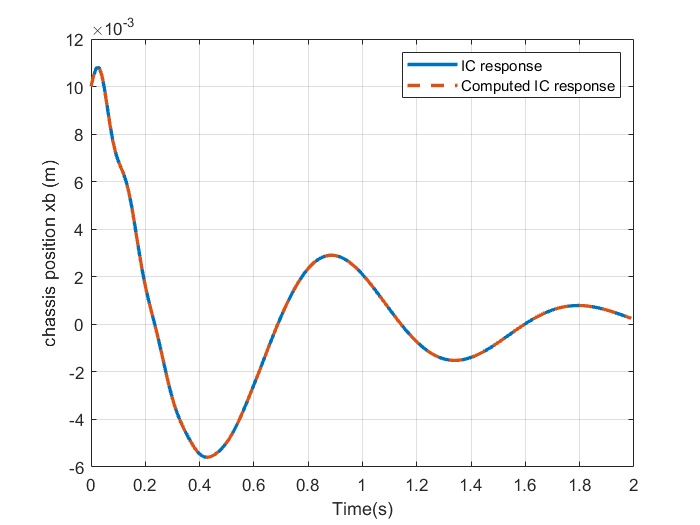

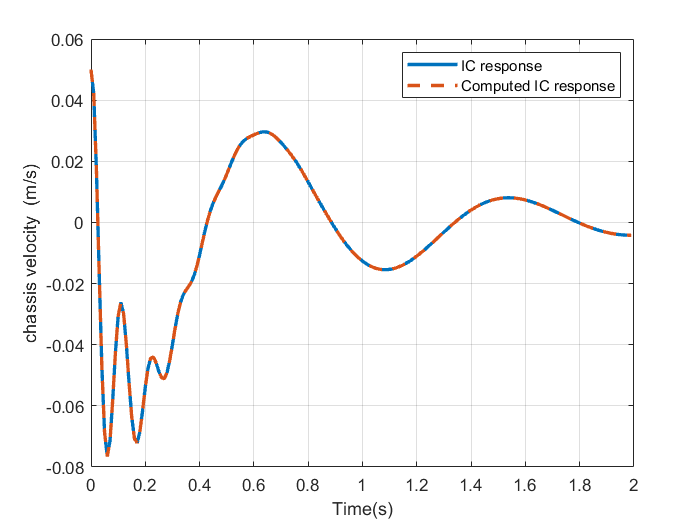

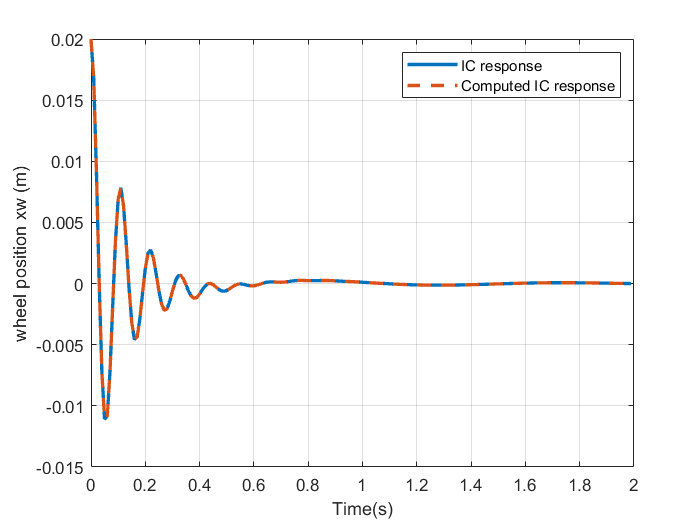

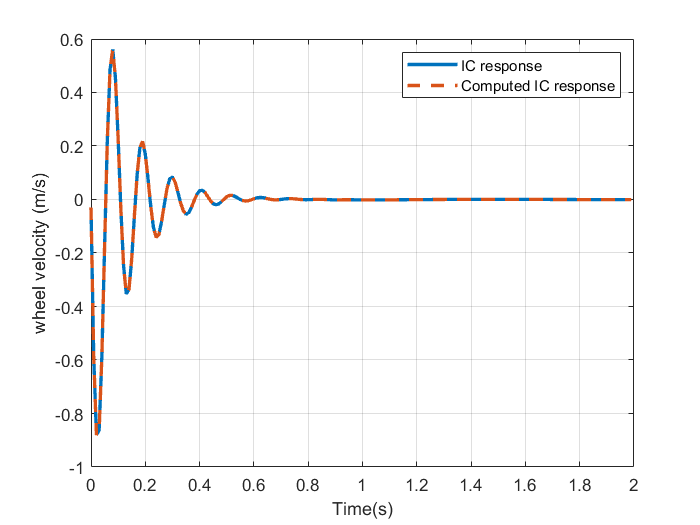

t = 0:.01:2-0.01;
%-- Let us first compute the IC response of our original system
u_ic = zeros(size(t)); % Define Input is zero for total run duration
x0_ic = [0.01 0.05 0.02 -0.03]; % Initial conditions are not zero.
%--- Simulate 
% lsim: Simulates the response of an LTI plant 
[Y_ic,t,X_ic] = lsim(qcar_CT,u_ic,t,x0_ic); % We want ouput, state information 

% Under the assumption that A is diagnolizable.

[Eig_vec,Eig_val] = eig(qcar_CT.A);
T_DCF = Eig_vec;
inT_DCF = inv(T_DCF);
% For the considered system we have 4 pole locations  (i.e. 2 complex conjugate poles)
ei = eig(A);
%--- Time Response corresponding to each pole
for i=1:length(t)
 P1(i) = exp(ei(1)*t(i)); % for first pole 
 P2(i) = exp(ei(2)*t(i)); % for second pole
 P3(i) = exp(ei(3)*t(i)); % for third pole
 P4(i) = exp(ei(4)*t(i)); % for fourth pole    
end    
%----
X_ic_comp = zeros(size(X_ic,1),size(X_ic,2));
% Total response
for i =1:length(t)
X_ic_comp(i,:) = real(P1(i)*T_DCF(:,1)*(inT_DCF(1,:)*x0_ic') + ...
P2(i)*T_DCF(:,2)*(inT_DCF(2,:)*x0_ic')+...
P3(i)*T_DCF(:,3)*(inT_DCF(3,:)*x0_ic')+...
P4(i)*T_DCF(:,4)*(inT_DCF(4,:)*x0_ic'));
end

%-- Comaprision
%- Initial response matches the sum of the response from modes
for i =1:4
figure;
plot(t,X_ic(:,i),'LineWidth',2); hold on; plot(t,X_ic_comp(:,i),'--','LineWidth',2);grid on;
legend('IC response','Computed IC response')
ylabel(states(i)); xlabel('Time(s)');
end

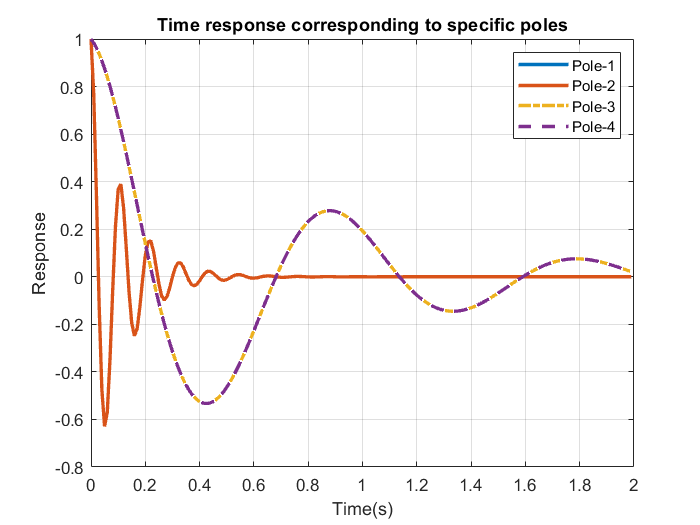

%-- Time response corresponding to each mode 
figure;
plot(t,real(P1),'LineWidth',2); grid on; hold on;
plot(t,real(P2),'-','LineWidth',2); grid on; hold on;
plot(t,real(P3),'-.','LineWidth',2); grid on; hold on;
plot(t,real(P4),'--','LineWidth',2); grid on; hold on;
ylabel('Response'); xlabel('Time(s)');
title('Time response corresponding to specific poles');
legend('Pole-1','Pole-2','Pole-3','Pole-4')

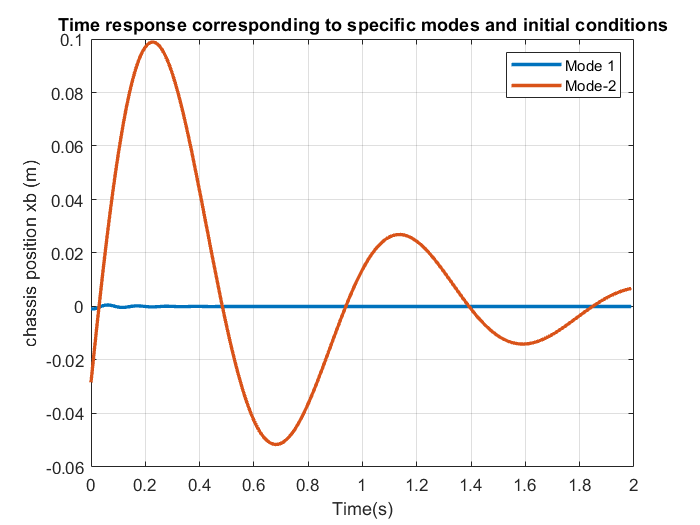

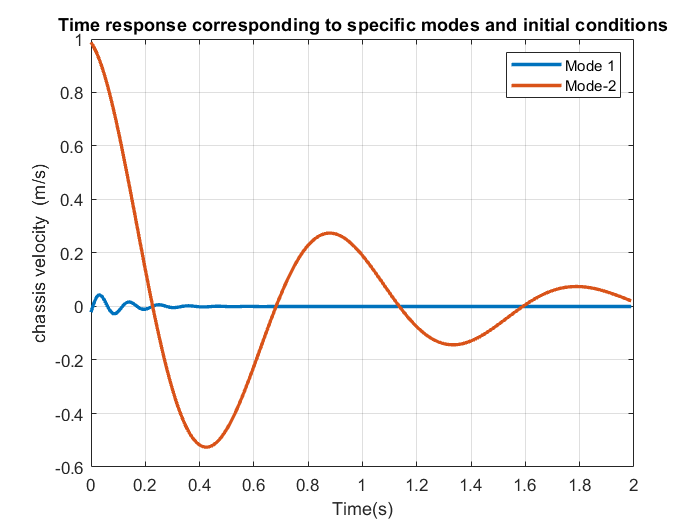

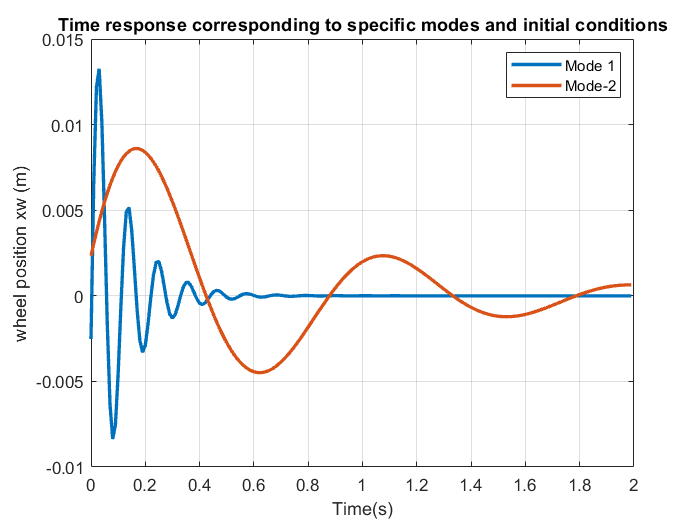

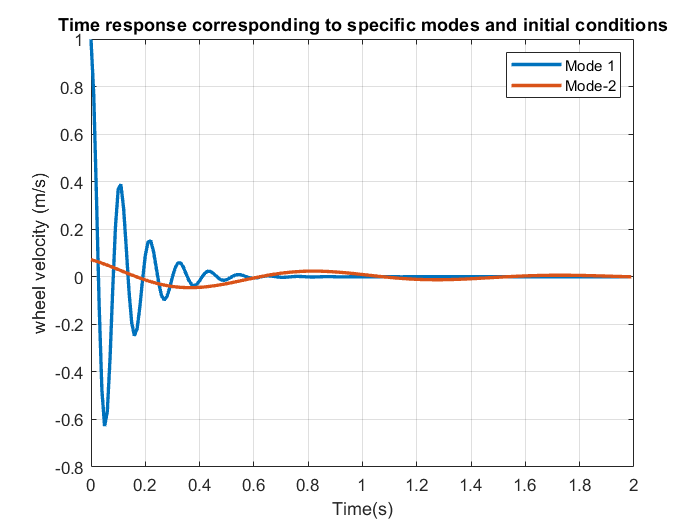

%--- What if we want to check how the initial condition affects each mode
%-- First mode
x_01 = real(T_DCF(:,1)); % Eigen vector corresponding to first mode
[Y_01,t,X_01] = lsim(qcar_CT,u_ic,t,x_01); % We want ouput, state information 
%-- Second mode
x_02 = real(T_DCF(:,3)); % Eigen vector corresponding to second mode
[Y_02,t,X_02] = lsim(qcar_CT,u_ic,t,x_02); % We want ouput, state information 
% Lets plot the state evolutions then
for i = 1:4
figure; 
plot(t,X_01(:,i),'LineWidth',2); grid on; hold on;
plot(t,X_02(:,i),'-','LineWidth',2); grid on; hold on;
ylabel(states(i)); xlabel('Time(s)');
title('Time response corresponding to specific modes and initial conditions');
legend('Mode-1','Mode-2')
end